clc
clear all
close all


# ELABORATO SERVOSYSTEMS & ROBOTICS

Link's dimentions expressed in meters:

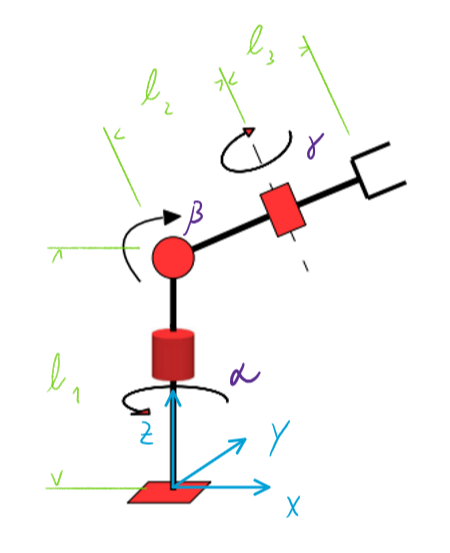

- Length of **Link 1**:

l1 = 1.2;

Link1 has a **Revolute Joint **that can freely rotate around the $z$ axis. $\alpha =\left\lbrack 0;\;2\pi \right\rbrack \ldotp$

- Length of **Link 2**:

l2 = 0.7;

Link2 has a **Revolute Joint **that can freely rotate in planes $y\;z$. $\beta =\left\lbrack 0;\;2\pi \right\rbrack$*. *

- Length of **Link 3**:

l3 = 0.4;

Link3 has a **Revolute Joint **that can freely rotate based on second link. $\gamma =\left\lbrack 0;\;2\pi \right\rbrack$.

L = [l1, l2, l3];

        **1. *****WORKING SPACE:***

- Posizioni:

Qmax = [0 0 0];
Qmin = [0 -pi/4 -0.95*pi];

- Plot Workingspace 3D:

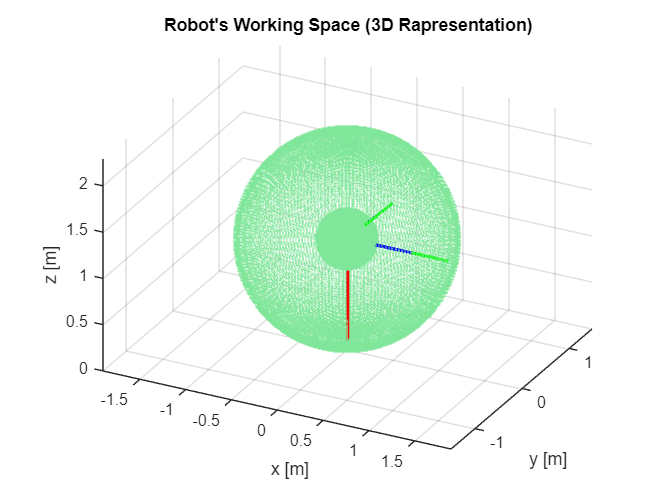

WS3D_AAA(L,Qmax,Qmin);

- Plot Workingspace 2D:

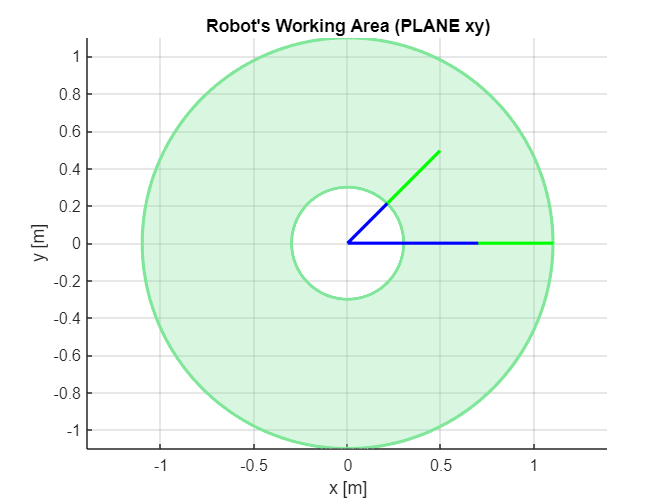

Qmin = [pi/4 0 -pi];
Qmax = [0 0 0];
WS2D_AAA(L,Qmax,Qmin,'xy');

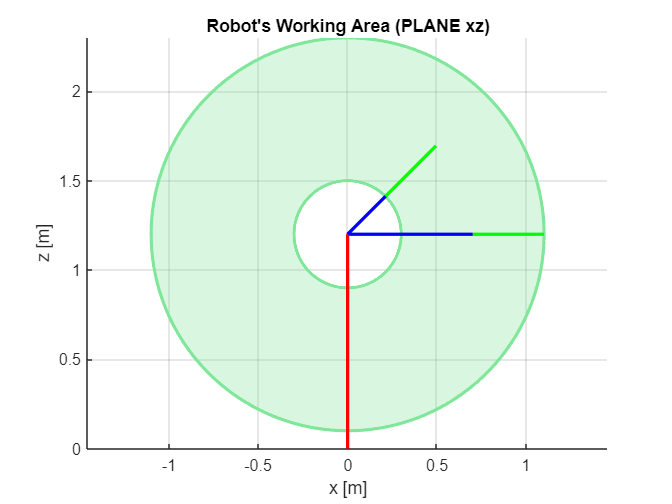

Qmin = [0 -pi/4 -pi];
Qmax = [0 0 0];
WS2D_AAA(L,Qmax,Qmin,'xz');

Da specifica non si plotta il piano yz, ma solo quelli sopra perchè

bastano a definire lo spazio di lavoro nelle loro viste.

% Qmin = [pi/2 -pi/4 -pi];
% Qmax = [-pi/2 0 0];
% WS2D_AAA(L,Qmax,Qmin,'yz');

** 2. SINGULARITY ANALISYS:**

- Robot data:

n = (pi^4);
toll = 1e-13;
max_angle = 2*pi;

dot_size = 3;

L = [l1, l2, l3];

a = linspace(0,max_angle,n);
b = linspace(0,max_angle,n);
c = linspace(0,max_angle,n);

S = [];
Sing = [];
R = [];


for i=a
    
    for j=b
       
        for k=c
           
            result = l3^3*cos(i)^2*cos(j)^3*cos(k)^2*sin(k) - l3^3*cos(j)*cos(k)^2*sin(i)^2*sin(k) - l3^3*cos(i)^2*cos(j)*cos(k)^2*sin(k) + l3^3*cos(j)^3*cos(k)^2*sin(i)^2*sin(k) + l2^2*l3*cos(i)^2*cos(j)^3*sin(k) + l2^2*l3*cos(j)^3*sin(i)^2*sin(k) - l2*l3^2*cos(i)^2*cos(j)*cos(k)*sin(k) - l2*l3^2*cos(j)*cos(k)*sin(i)^2*sin(k) + l3^3*cos(i)^2*cos(j)*cos(k)^2*sin(j)^2*sin(k) + l3^3*cos(j)*cos(k)^2*sin(i)^2*sin(j)^2*sin(k) + 2*l2*l3^2*cos(i)^2*cos(j)^3*cos(k)*sin(k) + l2^2*l3*cos(i)^2*cos(j)*sin(j)^2*sin(k) + 2*l2*l3^2*cos(j)^3*cos(k)*sin(i)^2*sin(k) + l2^2*l3*cos(j)*sin(i)^2*sin(j)^2*sin(k) + 2*l2*l3^2*cos(i)^2*cos(j)*cos(k)*sin(j)^2*sin(k) + 2*l2*l3^2*cos(j)*cos(k)*sin(i)^2*sin(j)^2*sin(k);
            
            if abs(result) < toll
                sing = [i;j;k];
                Sing = [Sing sing];
                R = [R result];
                q = [i,j,k];
                s = Direct_Kinematics_AAA(q,L);
                S = [S s];
            end
                        
        end
        
    end
    
end

- Plot Configurazioni Singolarità Giunti:

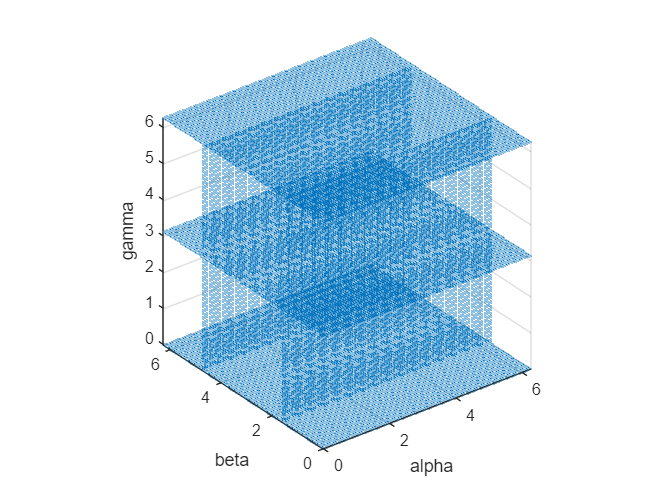

figure
title("Configurazioni Singolarità Giunti")
plot3(Sing(1,:),Sing(2,:),Sing(3,:),".","MarkerSize",dot_size)
xlabel('alpha')
ylabel('beta')
zlabel('gamma')
grid on
axis equal

- Plot Configurazioni Singolarità Spazio:

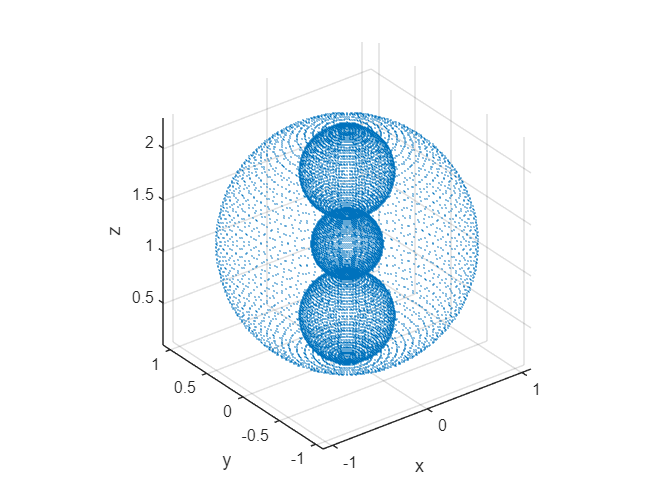

figure
title("Configurazioni Singolarità Spazio")
plot3(S(1,:),S(2,:),S(3,:),".","MarkerSize",dot_size)
xlabel('x')
ylabel('y')
zlabel('z')
grid on
axis equal

- Verifica singolarità con fimplicit:

% fun = @(i,j,k) l3^3*cos(i)^2*cos(j)^3*cos(k)^2*sin(k) - l3^3*cos(j)*cos(k)^2*sin(i)^2*sin(k) - l3^3*cos(i)^2*cos(j)*cos(k)^2*sin(k) + l3^3*cos(j)^3*cos(k)^2*sin(i)^2*sin(k) + l2^2*l3*cos(i)^2*cos(j)^3*sin(k) + l2^2*l3*cos(j)^3*sin(i)^2*sin(k) - l2*l3^2*cos(i)^2*cos(j)*cos(k)*sin(k) - l2*l3^2*cos(j)*cos(k)*sin(i)^2*sin(k) + l3^3*cos(i)^2*cos(j)*cos(k)^2*sin(j)^2*sin(k) + l3^3*cos(j)*cos(k)^2*sin(i)^2*sin(j)^2*sin(k) + 2*l2*l3^2*cos(i)^2*cos(j)^3*cos(k)*sin(k) + l2^2*l3*cos(i)^2*cos(j)*sin(j)^2*sin(k) + 2*l2*l3^2*cos(j)^3*cos(k)*sin(i)^2*sin(k) + l2^2*l3*cos(j)*sin(i)^2*sin(j)^2*sin(k) + 2*l2*l3^2*cos(i)^2*cos(j)*cos(k)*sin(j)^2*sin(k) + 2*l2*l3^2*cos(j)*cos(k)*sin(i)^2*sin(j)^2*sin(k);
% figure
% H = fimplicit3(fun,[0 2*pi]);